# **Introductory script illustrating how to fit a Weibul function to psychometric data (performance as a function of stimulus contrast)**

*This tutorial fits a cumulative Weibull function to a psychometric dataset using the Palamedes toolbox.*

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2019*

# **Step 1.** Load a dataset

Load some exemplar psychometric data

% Load exemplar data
[contrasts, fractionCorrect] = loadPerformanceData('ExemplarPsychometricFunction');

Locating project "ISETBioLiveScript" within "/Users/nicolas/Documents/MATLAB/projects".
  Found at "/Users/nicolas/Documents/MATLAB/projects/ISETBioLiveScript".


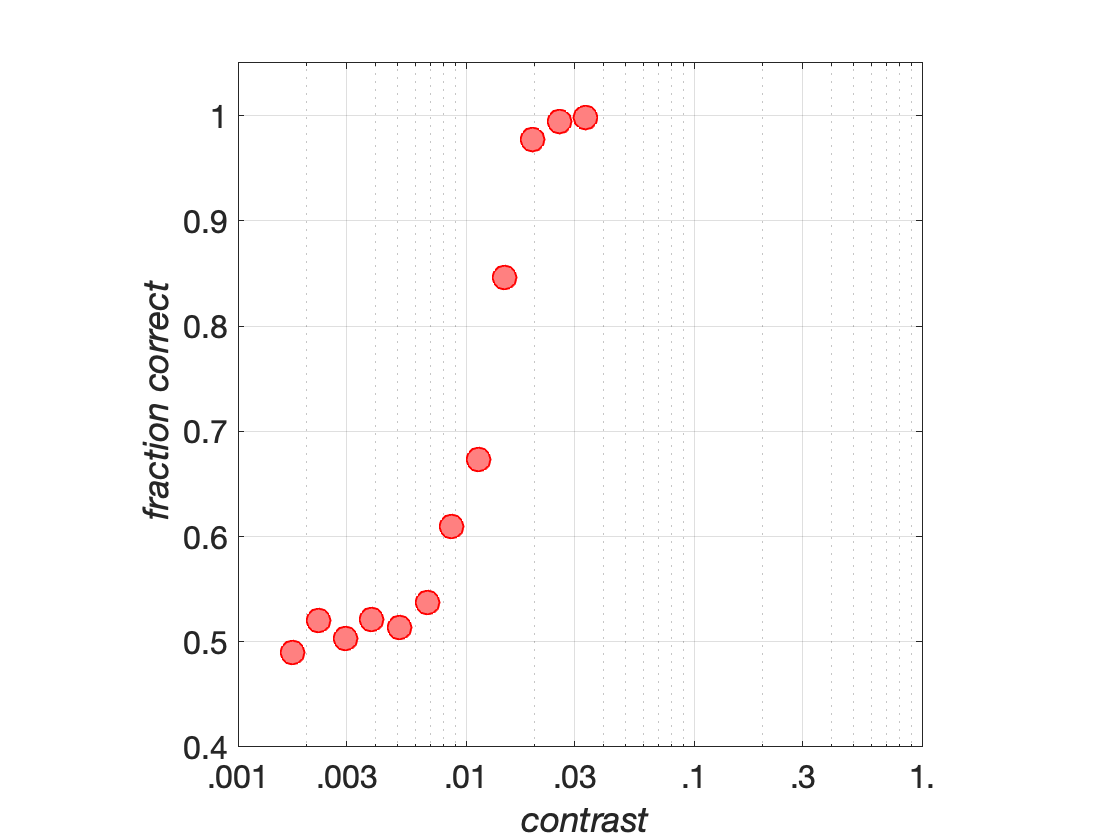


% Plot the data
plotPsychometricFunction(contrasts, fractionCorrect, 'scatter');

% Set up search grid
gridLevels = 100;
searchGrid.alpha = logspace(log10(min(contrasts)),log10(max(contrasts)),gridLevels);
searchGrid.beta = 10.^linspace(-4,4,gridLevels);
searchGrid.gamma = 0.5;
searchGrid.lambda = 0.0;

% Optimization settings for the fit
options             = optimset('fminsearch');
options.TolFun      = 1e-09;
options.MaxFunEvals = 1000;
options.MaxIter     = 1000;
options.Display     = 'off';

% Parameters for the curve fitting
nTrials    = 1024;
PF         = @PAL_Weibull;
paramsFree = [1 1 0 0];
numPos     = round(nTrials*fractionCorrect);
outOfNum   = repmat(nTrials,1,length(fractionCorrect));

% Use the Palamedes grid search method
[paramsValues,LL,flag] = PAL_PFML_Fit(contrasts(:), numPos(:), outOfNum(:), ...
            searchGrid, paramsFree, PF, 'SearchOptions', options);
        
% Get threshold
performanceAtThreshold = 0.71;
contrastThreshold = PF(paramsValues, performanceAtThreshold, 'inverse')

contrastThreshold = 0.0116

contrastSensitivity = 1/contrastThreshold

contrastSensitivity = 86.5747



contrasts = searchGrid.alpha;
psychometricFunction = PAL_Weibull(paramsValues, contrasts)

psychometricFunction =     0.5011    0.5012    0.5013    0.5014    0.5015    0.5016    0.5018    0.5020    0.5021    0.5023    0.5026    0.5028    0.5030    0.5033    0.5036    0.5039    0.5043    0.5047    0.5051    0.5056    0.5061    0.5067    0.5073    0.5079    0.5086    0.5094    0.5103    0.5112    0.5122    0.5133    0.5145    0.5158    0.5172    0.5188    0.5205    0.5223    0.5243    0.5264    0.5288    0.5313    0.5341    0.5371    0.5403    0.5439    0.5477    0.5518    0.5563    0.5611    0.5663    0.5719


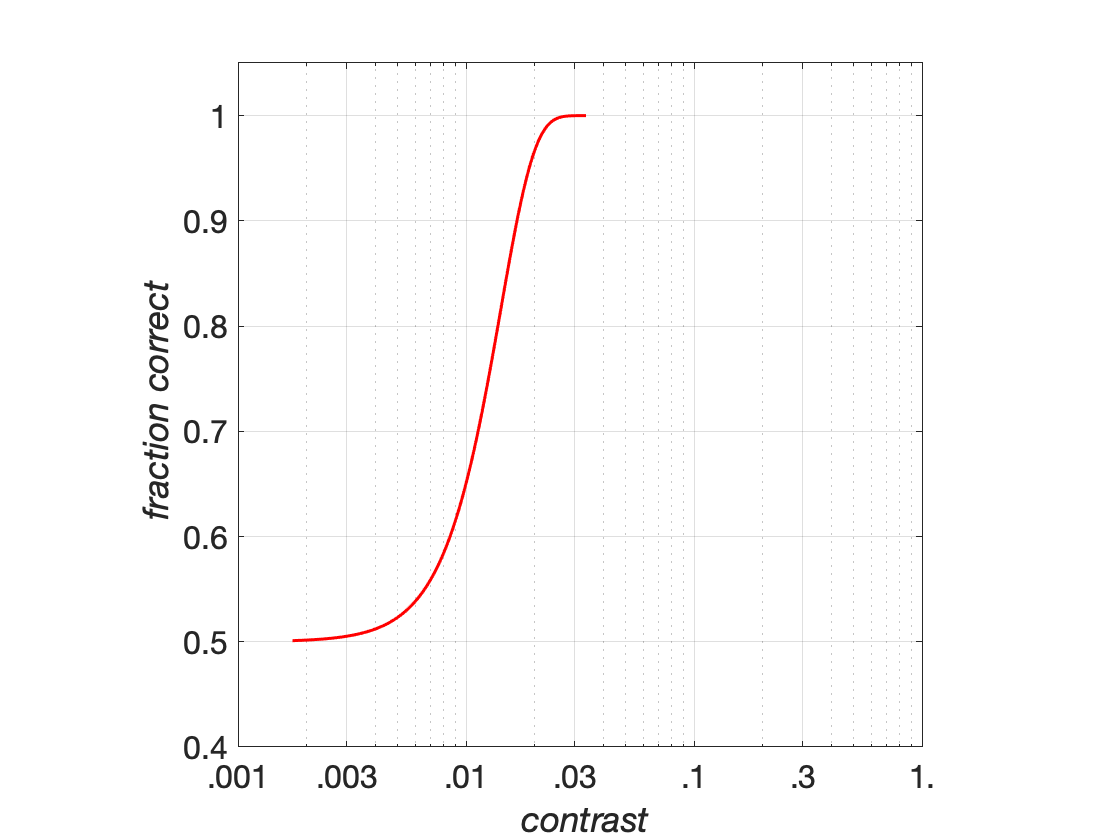

plotPsychometricFunction(contrasts, psychometricFunction, 'line');

function [contrasts, fractionCorrect] = loadPerformanceData(filename)
    rootDir = tbLocateProject('ISETBioLiveScript');
    dataFile = fullfile(rootDir, 'toolbox', 'resources', filename);
    load(dataFile, 'contrasts', 'fractionCorrect');
end

function plotPsychometricFunction(contrasts, fractionCorrect, plotType)
    figure()
    switch (plotType)
        case 'scatter'
            plot(contrasts,fractionCorrect, 'ko', 'MarkerSize', 12, ...
                'MarkerFaceColor', [1 0.5 0.5], 'MarkerEdgeColor', [1 0 0]);
        case 'line'
            plot(contrasts,fractionCorrect, 'r-', 'LineWidth', 1.5);
        otherwise
            error('Unknown plotType: ''%s''.', ployType);
    end
    contrastTicks = [0.001 0.003 0.01 0.03 0.1 0.3 1];
    contrastTickLabels = {'.001', '.003', '.01', '.03', '.1', '.3', '1.'};
    set(gca, 'XTick', contrastTicks, 'XTickLabel', contrastTickLabels, 'YTick', 0:0.1:1.0);
    set(gca, 'XLim', [0.001 1], 'YLim', [0.4 1.05], 'XScale', 'log')
    set(gca, 'FontSize', 16)
    xlabel('\it contrast');
    ylabel('\it fraction correct')
    axis 'square'
    grid on; box on
    
end